% Import data
data_HW3 = readtable("Top 100 Genes & Rand 15 Patients.xlsx")

data_HW3 = 17×101 table
           A_23_P342744            A_24_P246891                 A_23_P24535                                  A_23_P75362                                           A_32_P76399                                         A_23_P102973                                A_23_P133332                                             A_23_P257335                                            A_24_P192988                A_23_P151106                      A_23_P120970                                             A_24_P810290                                   A_23_P131825                               A_23_P206684                                     A_32_P32061                                        A_23_P79122            

% Using readmatrix correctly loads data as class "double"
data_HW3_2 = readmatrix("Top 100 Genes & Rand 15 Patients.xlsx");

% Create new X and Y matrices (have to convert class if using readtable)
X = str2double(data_HW3{3:end,1:100});
Y = table2array(data_HW3(3:end,end));

## Hold Out Validation Model

### Using Top 8 Correlated Genes from Training Set

% Create X and Y training/test sets from 100 genes
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, 0.7);

% Find correlation of all 100 genes and then extract data for top 8 genes
r_100 = corr(Xtrain,Ytrain);
[r_8,index_8] = maxk(abs(r_100),8);

% Create new training and test predictor data sets with top 8 genes 
Xtrain_8 = Xtrain(:,index_8);
Xtest_8 = Xtest(:,index_8);

mdl = fitlm(Xtrain_8,Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8

Estimated Coefficients:
                   Estimate      SE       tStat       pValue 
                   ________    ______    ________    ________

    (Intercept)     541.97     72.658      7.4592    0.017502
    x1              781.93     774.31      1.0098     0.41888
    x2              -262.1     290.85    -0.90115     0.46262
    x3             -215.64     312.91    -0.68913     0.56195
    x4             -60.782     279.71    -0.21731     0.84812
    x5             -48.045     135.39    -0.35487     0.75661
    x6              45.853     112.18     0.40875     0.72233
    x7             -14.706     67.364     -0.2183     0.84744
 

Ypred_norm = predict(mdl,Xtest_8);
r_norm = corr(Ytest,Ypred_norm)

r_norm = -0.3275

r2_norm = r_norm^2

r2_norm = 0.1073

RMSE = sqrt(mean((Ypred_norm-Ytest).^2))   

RMSE = 373.2615

avg_error = mean(abs(Ypred_norm-Ytest))

avg_error = 362.5492

## Lasso Regression

[B1, Fit] = lasso(Xtrain_8,Ytrain,"CV",10);
B1_coeff = B1(:,Fit.Index1SE)

B1_coeff =   524.7709
 -275.8472
         0
         0
    5.7321
    1.4539
         0
   41.8316


B1_intercept = Fit.Intercept(Fit.Index1SE)

B1_intercept = 540.3726

Ypred_lasso = Xtest_8 * B1_coeff + B1_intercept;

r_lasso = corr(Ypred_lasso,Ytest)

r_lasso = 0.0470

r2_lasso =  r_lasso^2

r2_lasso = 0.0022

RMSE_lasso = sqrt(mean((Ypred_lasso-Ytest).^2))   

RMSE_lasso = 359.4875

avg_error_lasso = mean(abs(Ypred_lasso-Ytest))

avg_error_lasso = 340.0633

## Stepwise Regression

[B2,~,~,~,stats] = stepwisefit(Xtrain_8,Ytrain);

Initial columns included: none
Step 1, added column 1, p=9.42884e-05
Step 2, added column 2, p=0.000269275
Final columns included:  1 2 
    'Coeff'        'Std.Err.'    'Status'    'P'         
    [ 658.6898]    [ 88.6731]    'In'        [7.4163e-05]
    [-317.7015]    [ 51.5258]    'In'        [2.6928e-04]
    [ -19.1992]    [100.8465]    'Out'       [    0.8544]
    [ -31.6687]    [ 58.5894]    'Out'       [    0.6056]
    [  51.6453]    [ 51.8154]    'Out'       [    0.3521]
    [  19.1949]    [ 41.8038]    'Out'       [    0.6600]
    [  11.9532]    [ 25.7376]    'Out'       [    0.6564]
    [  93.0919]    [ 61.0777]    'Out'       [    0.1713]



Ypred_step = Xtest_8*B2 + stats.intercept;
r_stepwise = corr(Ypred_step,Ytest)

r_stepwise = 0.1473

r2_stepwise =  r_stepwise^2

r2_stepwise = 0.0217

RMSE_stepwise = sqrt(mean((Ypred_step-Ytest).^2))   

RMSE_stepwise = 378.7734

avg_error_stepwise = mean(abs(Ypred_step-Ytest))

avg_error_stepwise = 354.5005

## Compare Results of 3 Methods

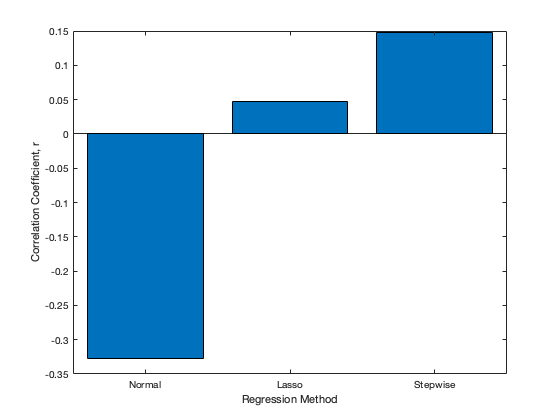

% Create labels for bar graphs
x = categorical({'Normal','Lasso','Stepwise'});
x = reordercats(x,{'Normal','Lasso','Stepwise'});

% Correlation bar graph
bar(x,[r_norm,r_lasso,r_stepwise])
xlabel("Regression Method")
ylabel("Correlation Coefficient, r")

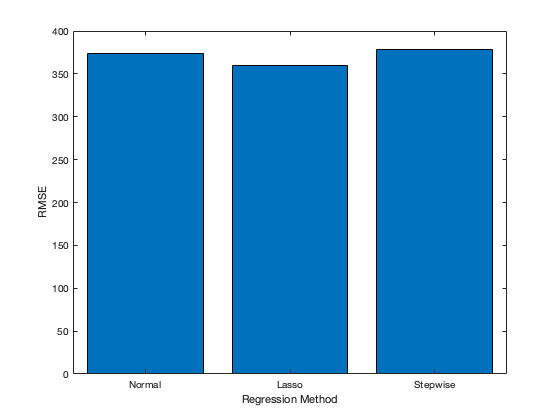

% RMSE bar graph
bar(x,[RMSE,RMSE_lasso,RMSE_stepwise])
xlabel("Regression Method")
ylabel("RMSE")

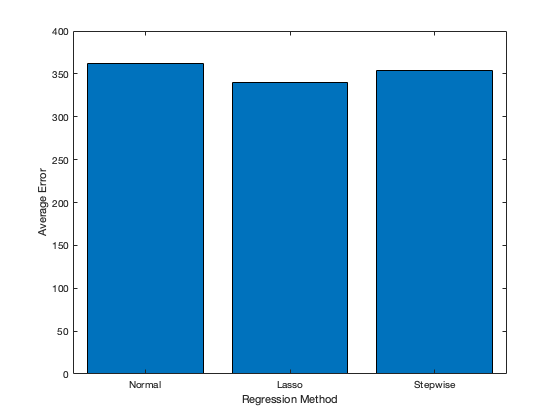

% Avg Error bar graph
bar(x,[avg_error,avg_error_lasso,avg_error_stepwise])
xlabel("Regression Method")
ylabel("Average Error")

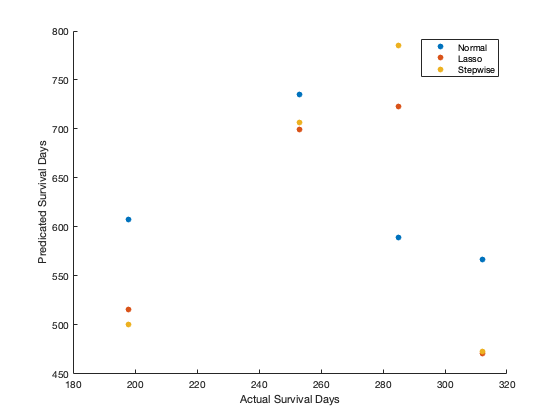

scatter(Ytest,Ypred_norm,"filled")
xlabel("Actual Survival Days")
ylabel("Predicated Survival Days")
hold on
scatter(Ytest,Ypred_lasso,"filled")
hold on
scatter(Ytest,Ypred_step,"filled")
hold off
legend("Normal","Lasso","Stepwise")